%ruta = pwd;

%dat = dir('*.xlsx');
%addpath(ruta);

%tamano = length(dat);

%datos = cell(1,tamano);

%s = size(tamano)


%for k = 1:tamano
 %   datos{1,k} = importdata(dat(k).name);
%end


%A = datos{1,1}.colheaders;
%b = datos{1,1}.data;
%b;
%c = datos{1,1}.data(:,2);

**ARRANCA LA LECTURA DE LOS DATOS**

% sacamos las caracteristicas

ruta = pwd;

dat = dir('*.xlsx');
tamano = length(dat);


for k = 1:tamano
   % Lectura de datos
    ecg1{1,k} = importdata(dat(k).name);
    ecg= ecg1{1, k}.data(:, 2);
    G = 250;
    Fs=500;
    
    ecgs=(ecg/G);
    ecgs=ecgs(~isnan(ecgs)) %cambiar valores nan por ceros
    
    ecgs=(ecgs-mean(ecgs))/std(ecgs); %centrar la señal
    t = (1:1:length(ecgs))*(1/Fs);
    
% Filtro

    orden = 200;
    limi = 59;
    lims = 61;
    limi_n = limi/(Fs/2); %normalización de lim inferior (frecuencia de nyquist)
    lims_n = lims/(Fs/2); %fnyquist=fs/2
    
    a = 1;
    b = fir1(orden,[limi_n lims_n],'stop');
    ecg_FIR = filtfilt(b,a,ecgs);

% Puntos R
    
    umbral_x = 0.3*Fs; 
    umbral_y = 6*mean(abs(ecg_FIR)); 
    
    [pks, locs] = findpeaks(ecg_FIR,'MinPeakHeight',umbral_y,'MinPeakDistance',umbral_x);
    %scatter(t(locs),pks,'filled')
    
    umbral_x1 = 0.15*Fs; 
    umbral_y1 = 0.5; 

    [pks1, locs1] = findpeaks(ecg_FIR,'MinPeakHeight',umbral_y1,'MinPeakDistance',umbral_x1);

    max_peak = mean(pks1)

    % Frecuencia cardiaca y variabilidad
    % de la frecuencia cardiaca VHR
    
    edad=[ecg1{1,k}.data(1, 4)];
    FCmax=208-(0.7*edad);
    disp('Frecuencia cardiaca máxima [lpm]: ');

    % HRV
    HRV=diff(t(locs));
    %stem(HRV);
    new_t=downsample(t,180);
    HRV_f= interp1(t(locs(1:end-1)),HRV,new_t);
    BPM=(1./HRV_f)*60;
    
    BPM1=BPM(~isnan(BPM));
    newt1=new_t(~isnan(BPM))

    % Puntos R-R
    %mRR
    suma=sum(HRV)
    mRR=suma/length(HRV);
    mRR_ms=mRR*1000;

    %RMSSD
    resta_RR=diff(HRV);
    resta_RR2=resta_RR.^2; 
    suma_resta_RR2= sum(resta_RR2);
    norm_resta_RR2=suma_resta_RR2/length(resta_RR);
    RMSSD=sqrt(norm_resta_RR2); %obtenida en segundos
    RMSSD_ms=RMSSD*1000;
    

    if  ((mRR_ms >=500 & mRR_ms<800) | (RMSSD_ms >=51))
        clas = 'Alto rendimiento'
    elseif  ((mRR_ms >=800 & mRR_ms<1000) | (RMSSD_ms >=30 & RMSSD_ms<51))
        clas = 'Rendimiento moderado'
    elseif  ((mRR_ms >=1000 & mRR_ms<1200)|(RMSSD_ms >=15 & RMSSD_ms<29))    
        clas = 'Aficionado'
    elseif (max_peak<3.5) | ((mRR_ms >=1200 | mRR_ms<500)|(RMSSD_ms <15))
        clas = 'Falla cardiaca'
    end
    
    caracte(k) = cellstr(clas);
    caracte = caracte';
   
    
   
    
end

ecgs =    -0.1080
   -0.1160
   -0.1200
   -0.1160
   -0.1200
   -0.1240
   -0.1280
   -0.1280
   -0.1360
   -0.1400


max_peak = 4.4360

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.1940

clas = 'Rendimiento moderado'

ecgs =     0.4840
    0.4800
    0.4840
    0.4840
    0.4840
    0.4840
    0.4800
    0.4600
    0.4320
    0.3840


max_peak = 5.0993

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 8.8560

clas = 'Alto rendimiento'

ecgs =    -0.4040
   -0.4040
   -0.4040
   -0.4040
   -0.4040
   -0.4080
   -0.4120
   -0.4080
   -0.4120
   -0.4160


max_peak = 3.8995

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 8.1800

clas = 'Alto rendimiento'

ecgs =     0.1480
    0.1520
    0.1520
    0.1520
    0.1520
    0.1520
    0.1560
    0.1560
    0.1560
    0.1560


max_peak = 4.3957

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420


suma = 7.5300

clas = 'Alto rendimiento'

ecgs =    -0.3320
   -0.3320
   -0.3280
   -0.3320
   -0.3360
   -0.3320
   -0.3320
   -0.3320
   -0.3320
   -0.3320


max_peak = 4.5351

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620


suma = 8.9020

clas = 'Alto rendimiento'

ecgs =     0.0720
    0.0720
    0.0720
    0.0720
    0.0720
    0.0760
    0.0760
    0.0800
    0.0840
    0.0800


max_peak = 3.8548

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.1060

clas = 'Rendimiento moderado'

ecgs =     1.1800
    1.0520
    0.8520
    0.6240
    0.3760
    0.1240
   -0.1240
   -0.3320
   -0.4960
   -0.6320


max_peak = 4.0691

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 7.7160

clas = 'Alto rendimiento'

ecgs =     0.8920
    0.8880
    0.8840
    0.8800
    0.8800
    0.8800
    0.8760
    0.8680
    0.8680
    0.8640


max_peak = 4.2561

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.6940

clas = 'Alto rendimiento'

ecgs =     0.1760
    0.1680
    0.1600
    0.1600
    0.1640
    0.1640
    0.1680
    0.1680
    0.1680
    0.1680


max_peak = 4.6039

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 8.0120

clas = 'Falla cardiaca'

ecgs =     1.4200
    1.4240
    1.4280
    1.4280
    1.4320
    1.4320
    1.4320
    1.4280
    1.4240
    1.4120


max_peak = 4.2182

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.3820

clas = 'Aficionado'

ecgs =    -0.4160
   -0.4160
   -0.4160
   -0.4160
   -0.4120
   -0.4080
   -0.4080
   -0.4040
   -0.4000
   -0.3960


max_peak = 4.0550

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.1400

clas = 'Aficionado'

ecgs =     0.0680
    0.0640
    0.0600
    0.0560
    0.0560
    0.0560
    0.0560
    0.0600
    0.0640
    0.0720


max_peak = 4.2909

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 8.7160

clas = 'Falla cardiaca'

ecgs =    -0.7720
   -0.7720
   -0.7720
   -0.7720
   -0.7720
   -0.7720
   -0.7720
   -0.7640
   -0.7560
   -0.7480


max_peak = 3.8357

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.5460

clas = 'Rendimiento moderado'

ecgs =    -0.8520
   -0.8520
   -0.8480
   -0.8480
   -0.8440
   -0.8440
   -0.8440
   -0.8440
   -0.8440
   -0.8400


max_peak = 3.6080

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620


suma = 8.0900

clas = 'Rendimiento moderado'

ecgs =     0.3880
    0.3920
    0.3960
    0.4000
    0.4040
    0.4080
    0.4080
    0.4120
    0.4160
    0.4240


max_peak = 4.1726

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.6960

clas = 'Alto rendimiento'

ecgs =    -0.5680
   -0.5760
   -0.5880
   -0.5960
   -0.6120
   -0.6280
   -0.6400
   -0.6520
   -0.6720
   -0.6840


max_peak = 4.0509

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.1460

clas = 'Rendimiento moderado'

ecgs =     0.1280
    0.1320
    0.1400
    0.1440
    0.1520
    0.1600
    0.1640
    0.1720
    0.1800
    0.1840


max_peak = 4.2784

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 8.8960

clas = 'Rendimiento moderado'

ecgs =     0.2760
    0.2760
    0.2800
    0.3000
    0.3360
    0.3840
    0.4480
    0.5400
    0.6560
    0.7960


max_peak = 4.2083

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620


suma = 8.8760

clas = 'Aficionado'

ecgs =     0.3160
    0.3120
    0.3160
    0.3160
    0.3080
    0.3120
    0.3120
    0.3120
    0.3120
    0.3160


max_peak = 4.7478

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.7600

clas = 'Alto rendimiento'

ecgs =     1.3600
    1.3600
    1.3600
    1.3640
    1.3640
    1.3640
    1.3640
    1.3680
    1.3680
    1.3640


max_peak = 3.9303

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.0960

clas = 'Alto rendimiento'

ecgs =    -0.1360
   -0.1320
   -0.1320
   -0.1320
   -0.1320
   -0.1320
   -0.1320
   -0.1360
   -0.1360
   -0.1360


max_peak = 4.7376

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.6040

clas = 'Alto rendimiento'

ecgs =    -1.0680
   -1.0600
   -1.0520
   -1.0360
   -1.0240
   -1.0120
   -1.0000
   -0.9960
   -0.9840
   -0.9760


max_peak = 4.0530

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 8.7060

clas = 'Alto rendimiento'

ecgs =    -0.8520
   -0.8480
   -0.8560
   -0.8560
   -0.8520
   -0.8520
   -0.8520
   -0.8520
   -0.8520
   -0.8520


max_peak = 3.1367

Frecuencia cardiaca máxima [lpm]: 


newt1 =     1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 8.3880

clas = 'Alto rendimiento'

ecgs =     0.2680
    0.2640
    0.2640
    0.2600
    0.2600
    0.2600
    0.2600
    0.2600
    0.2600
    0.2600


max_peak = 2.7470

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620


suma = 6.6720

clas = 'Rendimiento moderado'

ecgs =     0.0320
    0.0320
    0.0320
    0.0360
    0.0400
    0.0400
    0.0400
    0.0400
    0.0360
    0.0360


max_peak = 3.6619

Frecuencia cardiaca máxima [lpm]: 


newt1 =     0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.6220

clas = 'Rendimiento moderado'

ecgs = 4999×1
    0.1960
    0.2000
    0.2080
    0.2120
    0.2160
    0.2280
    0.2360
    0.2400
    0.2480
    0.2600


max_peak = 3.6441

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.5240

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.3680
   -0.3680
   -0.3680
   -0.3720
   -0.3760
   -0.3760
   -0.3720
   -0.3760
   -0.3760
   -0.3760


max_peak = 3.2754

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×20
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620


suma = 8.9560

clas = 'Alto rendimiento'

ecgs = 4999×1
    0.1040
    0.1000
    0.1000
    0.1040
    0.1040
    0.1040
    0.1080
    0.1080
    0.1080
    0.1080


max_peak = 4.5398

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×20
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 8.3820

clas = 'Alto rendimiento'

ecgs = 4999×1
   -0.5040
   -0.5040
   -0.5040
   -0.4960
   -0.4920
   -0.4920
   -0.4920
   -0.4960
   -0.4960
   -0.4960


max_peak = 4.3679

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.6140

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.6800
    0.6760
    0.6760
    0.6760
    0.6760
    0.6760
    0.6720
    0.6720
    0.6760
    0.6760


max_peak = 5.4419

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.4560

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.6400
   -0.6360
   -0.6320
   -0.6360
   -0.6320
   -0.6360
   -0.6320
   -0.6320
   -0.6320
   -0.6320


max_peak = 3.7550

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.8280

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.7800
   -0.7760
   -0.7800
   -0.7880
   -0.7920
   -0.7920
   -0.7960
   -0.8000
   -0.8080
   -0.8160


max_peak = 5.2509

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.4100

clas = 'Rendimiento moderado'

ecgs = 5000×1
    0.5120
    0.5120
    0.5120
    0.5120
    0.5040
    0.5000
    0.5000
    0.4920
    0.4920
    0.4880


max_peak = 5.0304

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.7260

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -1.5560
   -1.5560
   -1.5520
   -1.5480
   -1.5480
   -1.5480
   -1.5400
   -1.5400
   -1.5440
   -1.5480


max_peak = 2.3803

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×11
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220


suma = 5.1120

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.4000
    0.4080
    0.4160
    0.4240
    0.4280
    0.4360
    0.4440
    0.4480
    0.4560
    0.4560


max_peak = 4.5339

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×18
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 7.6780

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.1920
    0.1920
    0.1880
    0.1840
    0.1800
    0.1760
    0.1720
    0.1680
    0.1720
    0.1720


max_peak = 4.0401

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.1980

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.2200
   -0.2160
   -0.2120
   -0.2120
   -0.2040
   -0.1920
   -0.1840
   -0.1760
   -0.1720
   -0.1760


max_peak = 3.8430

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.6440

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.1520
    0.1520
    0.1520
    0.1600
    0.1600
    0.1600
    0.1600
    0.1640
    0.1560
    0.1480


max_peak = 3.9611

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.6860

clas = 'Alto rendimiento'

ecgs = 5000×1
    1.7760
    1.9600
    2.1400
    2.3120
    2.4880
    2.6600
    2.8240
    2.9560
    3.0320
    3.0640


max_peak = 3.5861

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 9.2520

clas = 'Aficionado'

ecgs = 5000×1
   -0.1120
   -0.1120
   -0.1080
   -0.1120
   -0.1120
   -0.1120
   -0.1160
   -0.1160
   -0.1160
   -0.1200


max_peak = 4.1337

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×20
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620


suma = 8.6200

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -1.0560
   -1.0480
   -1.0520
   -1.0520
   -1.0560
   -1.0520
   -1.0520
   -1.0560
   -1.0560
   -1.0560


max_peak = 3.1021

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×19
    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.3380

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.2840
    0.2720
    0.2560
    0.2440
    0.2360
    0.2320
    0.2080
    0.1840
    0.1680
    0.1640


max_peak = 3.7493

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×20
    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.3460

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.2320
   -0.2320
   -0.2360
   -0.2360
   -0.2400
   -0.2400
   -0.2400
   -0.2320
   -0.2360
   -0.2320


max_peak = 3.8397

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.9720

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.7640
   -0.7640
   -0.7600
   -0.7600
   -0.7600
   -0.7680
   -0.7720
   -0.7720
   -0.7760
   -0.7760


max_peak = 3.5715

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.9460

clas = 'Rendimiento moderado'

ecgs = 5000×1
    1.1520
    1.1560
    1.1600
    1.1600
    1.1600
    1.1600
    1.1600
    1.1600
    1.1640
    1.1600


max_peak = 3.1158

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620


suma = 8.9300

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.8520
   -0.8440
   -0.8400
   -0.8360
   -0.8320
   -0.8320
   -0.8360
   -0.8360
   -0.8320
   -0.8280


max_peak = 3.6947

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620


suma = 9.1800

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.5640
    0.5680
    0.5720
    0.5760
    0.5720
    0.5680
    0.5640
    0.5680
    0.5720
    0.5720


max_peak = 4.0676

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×24
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.6700

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.0120
    0.0200
    0.0240
    0.0240
    0.0200
    0.0120
    0.0040
   -0.0040
   -0.0160
   -0.0280


max_peak = 3.7674

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 8.8520

clas = 'Rendimiento moderado'

ecgs = 5000×1
    0.0640
    0.0720
    0.0720
    0.0840
    0.0880
    0.1000
    0.1040
    0.1160
    0.1280
    0.1440


max_peak = 4.1392

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.4280

clas = 'Alto rendimiento'

ecgs = 4999×1
    0.4040
    0.3960
    0.3960
    0.3920
    0.3880
    0.3880
    0.3880
    0.3840
    0.3840
    0.3840


max_peak = 3.6161

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×24
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420    9.0020


suma = 9.4720

clas = 'Rendimiento moderado'

ecgs = 5000×1
    0.0600
    0.0400
    0.0200
    0.0080
         0
   -0.0040
   -0.0040
   -0.0080
   -0.0120
   -0.0200


max_peak = 3.9213

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.0360

clas = 'Rendimiento moderado'

ecgs = 5000×1
    0.5240
    0.5240
    0.5280
    0.5280
    0.5320
    0.5320
    0.5320
    0.5360
    0.5320
    0.5400


max_peak = 4.2567

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.2580

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.8240
    0.8320
    0.8320
    0.8360
    0.8320
    0.8240
    0.8240
    0.8360
    0.8360
    0.8400


max_peak = 3.7171

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×24
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.5660

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.8360
   -0.8320
   -0.8280
   -0.8280
   -0.8280
   -0.8240
   -0.8240
   -0.8280
   -0.8280
   -0.8280


max_peak = 4.2958

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.2580

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.2840
    0.2880
    0.2880
    0.2880
    0.2880
    0.2880
    0.2840
    0.2880
    0.2880
    0.2920


max_peak = 3.6430

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×20
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620


suma = 8.2620

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.4400
   -0.4440
   -0.4480
   -0.4480
   -0.4480
   -0.4440
   -0.4440
   -0.4440
   -0.4400
   -0.4360


max_peak = 2.9116

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×17
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820


suma = 7.2200

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.0480
   -0.0440
   -0.0360
   -0.0280
   -0.0200
   -0.0160
   -0.0080
         0
    0.0040
    0.0080


max_peak = 3.3841

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 8.9960

clas = 'Rendimiento moderado'

ecgs = 4999×1
    0.4240
    0.4240
    0.4240
    0.4240
    0.4240
    0.4240
    0.4200
    0.4200
    0.4200
    0.4200


max_peak = 4.2107

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.5660

clas = 'Aficionado'

ecgs = 5000×1
   -0.7160
   -0.7120
   -0.7160
   -0.7200
   -0.7160
   -0.7160
   -0.7120
   -0.7080
   -0.7080
   -0.7040


max_peak = 4.2900

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.6380

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -0.8120
   -0.8160
   -0.8240
   -0.8280
   -0.8280
   -0.8240
   -0.8240
   -0.8240
   -0.8240
   -0.8240


max_peak = 3.8052

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×25
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420    9.0020


suma = 9.9320

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -0.3280
   -0.3280
   -0.3280
   -0.3280
   -0.3240
   -0.3200
   -0.3200
   -0.3160
   -0.3120
   -0.3120


max_peak = 4.2691

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.2560

clas = 'Aficionado'

ecgs = 4999×1
   -0.1040
   -0.1120
   -0.1120
   -0.1200
   -0.1200
   -0.1240
   -0.1240
   -0.1280
   -0.1240
   -0.1240


max_peak = 4.0395

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.6240

clas = 'Rendimiento moderado'

ecgs = 4999×1
   -0.4000
   -0.3960
   -0.3800
   -0.3560
   -0.3200
   -0.2640
   -0.2000
   -0.1160
   -0.0200
    0.0880


max_peak = 4.0103

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 9.1460

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.6000
   -0.5960
   -0.5920
   -0.5920
   -0.5880
   -0.5880
   -0.5920
   -0.5920
   -0.5880
   -0.5800


max_peak = 3.4374

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.6300

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -1.0600
   -1.0560
   -1.0600
   -1.0600
   -1.0600
   -1.0600
   -1.0600
   -1.0600
   -1.0600
   -1.0560


max_peak = 4.0823

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.5820

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.1720
    0.1720
    0.1720
    0.1720
    0.1680
    0.1640
    0.1680
    0.1680
    0.1680
    0.1680


max_peak = 4.5697

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×20
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 8.7400

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.1440
    0.1480
    0.1560
    0.1600
    0.1680
    0.1800
    0.1920
    0.1920
    0.1920
    0.1880


max_peak = 3.7630

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.5820

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.1840
    0.1760
    0.1600
    0.1480
    0.1320
    0.1160
    0.1080
    0.1040
    0.1000
    0.0960


max_peak = 3.5022

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×24
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420    9.0020


suma = 9.3660

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.3560
   -0.3560
   -0.3560
   -0.3560
   -0.3560
   -0.3600
   -0.3560
   -0.3600
   -0.3600
   -0.3640


max_peak = 3.9687

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.1260

clas = 'Alto rendimiento'

ecgs = 5000×1
    1.0960
    1.0880
    1.0880
    1.0800
    1.0800
    1.0800
    1.0720
    1.0680
    1.0680
    1.0720


max_peak = 2.7312

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×7
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820


suma = 8.1640

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.1200
    0.1160
    0.1160
    0.1160
    0.1120
    0.1120
    0.1080
    0.1080
    0.1120
    0.1120


max_peak = 4.0648

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.3100

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -0.0040
   -0.0080
   -0.0040
    0.0040
    0.0120
    0.0120
    0.0040
         0
    0.0040
    0.0040


max_peak = 3.7670

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×25
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420    9.0020


suma = 9.8080

clas = 'Rendimiento moderado'

ecgs = 5000×1
    2.4560
    2.4520
    2.4520
    2.4520
    2.4560
    2.4520
    2.4520
    2.4520
    2.4520
    2.4560


max_peak = 2.7946

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×16
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620


suma = 6.6600

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.7640
   -0.7640
   -0.7560
   -0.7520
   -0.7520
   -0.7560
   -0.7600
   -0.7600
   -0.7600
   -0.7600


max_peak = 4.1792

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.0360

clas = 'Alto rendimiento'

ecgs = 5000×1
    1.1120
    1.1120
    1.1080
    1.1000
    1.1000
    1.0960
    1.0920
    1.0960
    1.0960
    1.0960


max_peak = 2.4955

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×11
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220


suma = 5.2900

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.1920
    0.1880
    0.1920
    0.1840
    0.1800
    0.1760
    0.1720
    0.1680
    0.1640
    0.1640


max_peak = 4.1286

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.1980

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.5480
    0.5480
    0.5480
    0.5520
    0.5520
    0.5520
    0.5520
    0.5520
    0.5520
    0.5480


max_peak = 3.4229

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 9.3420

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -0.6400
   -0.6360
   -0.6360
   -0.6360
   -0.6360
   -0.6400
   -0.6400
   -0.6400
   -0.6400
   -0.6400


max_peak = 4.8304

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×19
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 8.3560

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.3160
    0.3120
    0.3120
    0.3080
    0.3000
    0.2960
    0.3080
    0.3200
    0.3320
    0.3240


max_peak = 4.1154

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.6680

clas = 'Alto rendimiento'

ecgs = 4999×1
    0.0640
    0.0680
    0.0720
    0.0640
    0.0600
    0.0640
    0.0680
    0.0720
    0.0720
    0.0720


max_peak = 2.9951

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.8440

clas = 'Alto rendimiento'

ecgs = 4999×1
    0.2520
    0.2560
    0.2520
    0.2520
    0.2520
    0.2520
    0.2480
    0.2440
    0.2440
    0.2440


max_peak = 3.5297

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.7740

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.2120
   -0.2120
   -0.2080
   -0.2080
   -0.2040
   -0.2040
   -0.2040
   -0.2000
   -0.2000
   -0.1960


max_peak = 3.7939

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×20
    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.5220

clas = 'Alto rendimiento'

ecgs = 4999×1
    0.1440
    0.1400
    0.1360
    0.1360
    0.1320
    0.1320
    0.1280
    0.1280
    0.1240
    0.1240


max_peak = 3.4906

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 9.2180

clas = 'Alto rendimiento'

ecgs = 4999×1
   -1.4000
   -1.4000
   -1.4000
   -1.4000
   -1.4000
   -1.4000
   -1.4000
   -1.4040
   -1.4040
   -1.4000


max_peak = 2.8370

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×19
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 8.5860

clas = 'Alto rendimiento'

ecgs = 4999×1
    0.1240
    0.1240
    0.1240
    0.1240
    0.1240
    0.1240
    0.1240
    0.1240
    0.1200
    0.1240


max_peak = 4.3408

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×18
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020


suma = 7.9620

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -0.7600
   -0.7560
   -0.7600
   -0.7600
   -0.7640
   -0.7600
   -0.7600
   -0.7600
   -0.7600
   -0.7600


max_peak = 4.5815

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 9.1140

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.9120
   -0.9200
   -0.9160
   -0.9200
   -0.9200
   -0.9160
   -0.9160
   -0.9120
   -0.9120
   -0.9160


max_peak = 6.8411

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.9980

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.3040
   -0.3240
   -0.3400
   -0.3520
   -0.3520
   -0.3520
   -0.3440
   -0.3320
   -0.3240
   -0.3280


max_peak = 6.0604

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×24
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.5860

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -0.4280
   -0.4280
   -0.4280
   -0.4280
   -0.4320
   -0.4360
   -0.4360
   -0.4360
   -0.4360
   -0.4360


max_peak = 8.0102

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×20
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.4820

clas = 'Alto rendimiento'

ecgs = 4999×1
    0.2880
    0.2880
    0.2920
    0.2920
    0.2920
    0.2920
    0.2920
    0.2960
    0.2960
    0.2960


max_peak = 5.0665

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×24
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.6160

clas = 'Rendimiento moderado'

ecgs = 5000×1
    0.8440
    0.8440
    0.8480
    0.8520
    0.8480
    0.8480
    0.8440
    0.8480
    0.8520
    0.8600


max_peak = 3.3548

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×20
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 8.2020

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -0.0680
   -0.0640
   -0.0720
   -0.0680
   -0.0680
   -0.0600
   -0.0560
   -0.0400
   -0.0360
   -0.0400


max_peak = 4.1761

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.5300

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -0.2360
   -0.2360
   -0.2360
   -0.2360
   -0.2360
   -0.2360
   -0.2400
   -0.2400
   -0.2360
   -0.2360


max_peak = 4.1748

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220


suma = 9.1680

clas = 'Aficionado'

ecgs = 5000×1
   -0.5200
   -0.5120
   -0.5080
   -0.5040
   -0.5040
   -0.5040
   -0.5080
   -0.5120
   -0.5120
   -0.5080


max_peak = 4.9351

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 8.7940

clas = 'Aficionado'

ecgs = 5000×1
   -0.8920
   -0.8960
   -0.8920
   -0.8920
   -0.8960
   -0.8920
   -0.8840
   -0.8880
   -0.8920
   -0.8920


max_peak = 4.7353

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×24
    0.3620    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.7360

clas = 'Alto rendimiento'

ecgs = 5000×1
    0.4080
    0.4120
    0.4120
    0.4120
    0.4120
    0.4160
    0.4120
    0.4120
    0.4160
    0.4160


max_peak = 4.1537

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×20
    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.7580

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -0.2560
   -0.2560
   -0.2520
   -0.2520
   -0.2520
   -0.2480
   -0.2480
   -0.2480
   -0.2480
   -0.2480


max_peak = 4.2902

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×23
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.4120

clas = 'Rendimiento moderado'

ecgs = 5000×1
    0.4880
    0.4840
    0.4800
    0.4760
    0.4760
    0.4760
    0.4720
    0.4640
    0.4560
    0.4480


max_peak = 3.6207

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×21
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.5660

clas = 'Alto rendimiento'

ecgs = 5000×1
   -0.2600
   -0.2680
   -0.2720
   -0.2720
   -0.2800
   -0.2760
   -0.2800
   -0.2800
   -0.2840
   -0.2880


max_peak = 4.1139

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    0.7220    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820


suma = 8.8060

clas = 'Rendimiento moderado'

ecgs = 5000×1
   -0.5240
   -0.5240
   -0.5240
   -0.5240
   -0.5200
   -0.5160
   -0.5160
   -0.5120
   -0.5120
   -0.5120


max_peak = 4.0483

Frecuencia cardiaca máxima [lpm]: 


newt1 = 1×22
    1.0820    1.4420    1.8020    2.1620    2.5220    2.8820    3.2420    3.6020    3.9620    4.3220    4.6820    5.0420    5.4020    5.7620    6.1220    6.4820    6.8420    7.2020    7.5620    7.9220    8.2820    8.6420


suma = 9.1500

clas = 'Rendimiento moderado'

% Del anterior codigo los datos nos quedaron desordenados
% El comando sort lo que hace es ordenarnos los datos, en este caso por
% abecedario
orden = sort(caracte);
orden

orden = 100×1 cell array
    {'Aficionado'      }
    {'Aficionado'      }
    {'Aficionado'      }
    {'Aficionado'      }
    {'Aficionado'      }
    {'Aficionado'      }
    {'Aficionado'      }
    {'Aficionado'      }
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}
    {'Alto rendimiento'}



save("Caracteristicas.mat","caracte");

#### AQUI ARRANCA LA NEURONA

% Comenzamos a declarar los rangos de lectura para cada
% Caracteristica que hemos
% Esto se conoce como DeepLearning

clases = cell(100, 1);
clases(1:8) = {'Aficionado'};
clases(9:66) = {'Alto'};
clases(67:68)={'Falla'}

clases = 100×1 cell array
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }


clases(69:100)={'Moderado'}

clases = 100×1 cell array
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }


neuro=fitnet([10 8 8 10])

neuro =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 5
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 260
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1; 1]
      

a=ones(8,1)*3

a =      3
     3
     3
     3
     3
     3
     3
     3


b=ones(58,1)

b =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


c=ones(2,1)*4

c =      4
     4


d=ones(32,1)*2

d =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


clasesN=[b;d;a;c]

clasesN =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


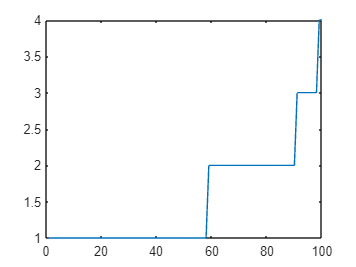

plot(clasesN)

dataEntr2=orden;
clasesEntr2= clasesN;
dataPr2=orden;
clasesPr2=clasesN;

clasesEntr2(1:16)=[];
clasesEntr2(41:50)=[];
clasesEntr2(67:70)=[];
% %clasesEntr2(70)=[];

dataEntr2(1:16,:)=[];
dataEntr2(41:50,:)=[];
dataEntr2(67:70,:)=[];
%dataEntr2(70,:)=[];

%30 elementos de prueba
clasesPr2(16:59)=[];
clasesPr2(25:48)=[];
clasesPr2(25:26)=[];
% clasesPr2(31)=[];
 
dataPr2(16:59,:)=[];
dataPr2(25:48,:)=[];
dataPr2(25:26,:)=[];
%dataPr2(31,:)=[];

neuro=train(neuro,dataEntr2',clasesEntr2');

Error using nntraining.setup>setupPerWorker
Inputs X{1,1} is not numeric or logical.

Error in nntraining.setup (line 77)
  [net,data,tr,err] = setupPerWorker(net,trainFcn,X,Xi,Ai,T,EW,enableConfigure);

Error in network/train (line 336)
[net,data,tr,err] = nntraining.setup(net,net.trainFcn,X,Xi,Ai,T,EW,enableConfigure,isComposite

%obtener los datos
resred2=round(sim(neuro,dataPr2'));
plot(resred2)

confusionchart(clasesPr2,resred2)

%matriz de confusion
confusionchart(clasesPr2,resred2,'ColumnSummary','column-normalized','RowSummary','row-normalized','Title','Matriz de confusión Red 1')